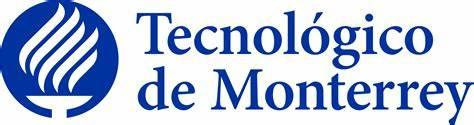

**Actividad de cierre.**

**Fundamentación de robótica gpo 101**

**Hecho por:**

A01736171 | Jesús Alejandro Gómez Bautista

 ITESM puebla

**Profesor:**

Alfredo García Suárez.

*01 de mazo del 2024.*

**Ejercicio.**

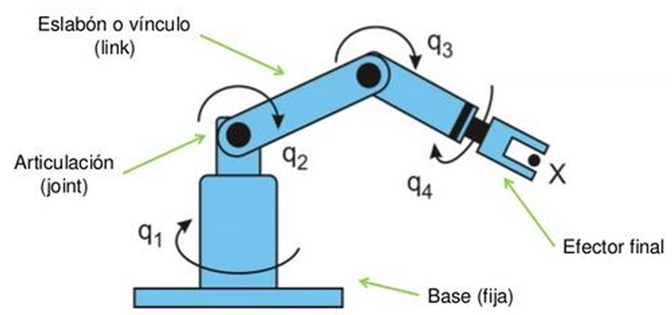

**Marco de referencia establecido.**

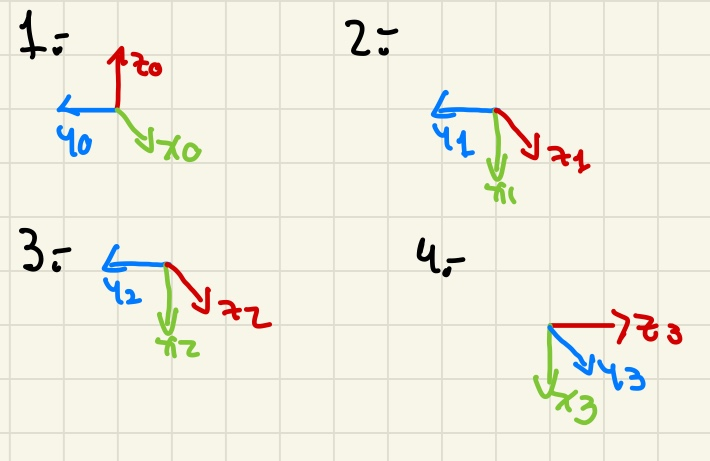

Para la primera junta, en el caso de la rotación lo que se quiere es captar el angulo que se mueve respecte al eje z según el marco de referencia 1, por lo tanto se debe de poner la matriz de rotación de z, pero de la misma manera lo que se debe de hacer mover el marco de referencia para que esta vez z quede respecto al eje de rotación de la segunda junta, esto se hará rotando en y -90 grados, lo único que se debe de hacer es multiplicar las dos matrices de rotación (primero sobre el eje z y luego sobre el eje y). Para el caso de la translación lo único que debe de hacer es subir l1 en el eje z, debido a que no existe una variación, por lo tanto se le pone l1 en el eje de z y en los otros dos ejes se les pone 0.

En el caso de la segunda junta, respecto al marco de referencia 2, lo que se tuvo que hacer fue solamente ver la rotación que se tiene en respecto al eje z, por lo tanto solamente se agrega la matriz de rotación en z. Hablando de la translación, al momento de hacer el análisis, con respecto del eje x lo que se podrá obtener es el cateto opuesto, por lo tanto se usará el seno del ángulo por l2 y en el caso del eje y lo que nos dará será el cateto adyacente, por lo tanto lo que se debe hacer es poner l2 por el coseno del ángulo.

En el caso de la tercera junta, respecto al marco de referencia 3, lo primero que se debe de hacer es ver la rotación que tiene en el eje z, por lo tanto de la misma manera se agrega la matriz de rotación del eje z, pero de la misma manera se debe de cambiar el marco (para el marco número 4), esto se podrá lograr rotando el eje -90 grados en x, por lo tanto se multiplican las dos matrices, en ese orden (primero sobre el eje z y luego sobre el eje x). Hablando de la translación sería la misma lógica que en la anterior junta, a diferencia que se trabajará con l3 y el ángulo 3.

Para la última junta, hablando de la rotación lo que se debe de hacer es solamente ver la rotación que tiene respecto al eje de z, por lo tanto se le pone esa matriz de rotación en z. Hablando de la translacion, esta se moverá sobre el eje z el valor de l4, por lo tanto lo que debe de hacer es poner l4 en z y los otros dos ejes se quedan con el valor de cero.

Con este análisis se pone en el código, dando el siguente resultado.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) l1 l2 l3 l4 t r

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3,th4];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1]*[0  0 -1 ;0  1  0; 1  0  0];


%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*sin(th2); l2*cos(th2);0];
%Matriz de rotación de la junta 2 respecto a 1  -90º y1 
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [l3*sin(th3); l3*cos(th3);0];  
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,3)= [cos(th3) -sin(th3)  0;
           sin(th3)  cos(th3)  0;
           0         0         1]*[1 0 0 ;0  0  1; 0  -1  0];
P(:,:,4)= [r; r ; l4];
%Matriz de rotación de la junta 2 respecto a 1  -90º y1 
R(:,:,4)= [cos(th4) -sin(th4)  0;
           sin(th4)  cos(th4)  0;
           0         0         1];



%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/ 0, -sin(th1(t)), -cos(th1(t)),  0 \
|                                   |
| 0,  cos(th1(t)), -sin(th1(t)),  0 |
|                                   |
| 1,       0,            0,      l1 |
|                                   |
\ 0,       0,            0,       1 /



Matriz de Transformación global T2


/ -sin(th1(t)) sin(th2(t)), -cos(th2(t)) sin(th1(t)), -cos(th1(t)), -l2 cos(th2(t)) sin(th1(t)) \
|                                                                                               |
|  cos(th1(t)) sin(th2(t)),  cos(th1(t)) cos(th2(t)), -sin(th1(t)),  l2 cos(th1(t)) cos(th2(t)) |
|                                                                                               |
|        cos(th2(t)),             -sin(th2(t)),             0,          l1 + l2 sin(th2(t))     |
|                                                                                               |
\             0,                        0,                  0,                   1              /



Matriz de Transformación global T3


/ -sin(th1(t)) sin(#1), cos(th1(t)), -sin(th1(t)) cos(#1),          -sin(th1(t)) #2         \
|                                                                                           |
|  cos(th1(t)) sin(#1), sin(th1(t)),  cos(th1(t)) cos(#1),          cos(th1(t)) #2          |
|                                                                                           |
|        cos(#1),            0,            -sin(#1),       l1 + l2 sin(th2(t)) - l3 sin(#3) |
|                                                                                           |
\           0,               0,                0,                          1                /

where

   #1 == th2(t) + th3(t)

   #2 == l2 cos(th2(t)) + l3 cos(#3)

   #3 == th2(t) - th3(t)




Matriz de Transformación global T4


[[cos(th1(t)) sin(th4(t)) - cos(th4(t)) sin(th1(t)) sin(#1), cos(th1(t)) cos(th4(t)) + sin(th1(t)) sin(th4(t)) sin(#1), -sin(th1(t)) cos(#1),

  r cos(th1(t)) - sin(th1(t)) #2 - l4 sin(th1(t)) cos(#1) - r sin(th1(t)) sin(#1)],

  [sin(th1(t)) sin(th4(t)) + cos(th1(t)) cos(th4(t)) sin(#1), cos(th4(t)) sin(th1(t)) - cos(th1(t)) sin(th4(t)) sin(#1),

  cos(th1(t)) cos(#1), r sin(th1(t)) + cos(th1(t)) #2 + l4 cos(th1(t)) cos(#1) + r cos(th1(t)) sin(#1)],

  [cos(th4(t)) cos(#1), -sin(th4(t)) cos(#1), -sin(#1), l1 + l2 sin(th2(t)) + r cos(#1) - l4 sin(#1) - l3 sin(#3)],

  [0, 0, 0, 1]]

where

   #1 == th2(t) + th3(t)

   #2 == l2 cos(th2(t)) + l3 cos(#3)

   #3 == th2(t) - th3(t)






%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
%Jv11= functionalDerivative(PO(1,1,GDL), l1);
%Jv12= functionalDerivative(PO(1,1,GDL), l2);
%Derivadas parciales de y respecto a th1 y th2
%Jv21= functionalDerivative(PO(2,1,GDL), l1);
%Jv22= functionalDerivative(PO(2,1,GDL), l2);
%Derivadas parciales de z respecto a th1 y th2
%Jv31= functionalDerivative(PO(3,1,GDL), l1);
%Jv32= functionalDerivative(PO(3,1,GDL), l2);

%Creamos la matríz del Jacobiano lineal
%jv_d=simplify([Jv11 Jv12;
%              Jv21 Jv22;
%              Jv31 Jv32]);
%pretty(jv_d);


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

[[#2 sin(th1(t)) #6 - #3 sin(th1(t)) #5 - #4 (r sin(th1(t)) + cos(th1(t)) #7 + l4 cos(th1(t)) cos(#8) + r cos(th1(t)) sin(#8))

   + r #1 (cos(th1(t)) + sin(th1(t)) sin(#8))],

  [#3 cos(th1(t)) #5 - #2 cos(th1(t)) #6 - #4 (sin(th1(t)) #7 - r cos(th1(t)) + l4 sin(th1(t)) cos(#8) + r sin(th1(t)) sin(#8))

   + r #1 (sin(th1(t)) - cos(th1(t)) sin(#8))],

  [- #2 (l4 cos(#8) + r sin(#8) + l3 cos(#10)) - #3 (#9 + l4 cos(#8) + r sin(#8) + l3 cos(#10)) - r #1 cos(#8)]]

where

         _________
          d
   #1 == -- th4(t)
         dt

         _________
          d
   #2 == -- th3(t)
         dt

         _________
          d
   #3 == -- th2(t)
         dt

         _________
          d
   #4 == -- th1(t)
         dt

   #5 == l2 sin(th2(t)) + r cos(#8) - l4 sin(#8) - l3 sin(#10)

   #6 == l4 sin(#8) - r cos(#8) + l3 sin(#10)

   #7 == #9 + l3 cos(#10)

   #8 == th2(t) + th3(t)

   #9 == l2 cos(th2(t))

   #10 == th2(t) - th3(t)




disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/ - #4 cos(th1(t)) - #3 cos(th1(t)) - #1 sin(th1(t)) cos(#2) \
|                                                            |
|  #1 cos(th1(t)) cos(#2) - #3 sin(th1(t)) - #4 sin(th1(t))  |
|                                                            |
|                   _________                                |
|                    d                                       |
|                   -- th1(t) - #1 sin(#2)                   |
\                   dt                                       /

where

         _________
          d
   #1 == -- th4(t)
         dt

   #2 == th2(t) + th3(t)

         _________
          d
   #3 == -- th3(t)
         dt

         _________
          d
   #4 == -- th2(t)
         dt




**Conclusiones y análisis de resultados.**

Velocidad lineal: en cuanto a la velocidad lineal, podemos ver que x,y,z dependen únicamente de las magnitudes de theta (1, 2, 3 y 4) en funciones trignométricas de senos y cosenos (esto por la composición de la posición en x dada para las articulaciones 2 y 3, cuyas dimensiones en x y y eran producto de la longitud de la articulación por el cateto opuesto o adyacente del angulo de la rotación), las derivadas de los 4 ángulos de las articulaciones (pues ejercen influencia en la velocidad lineal que estas provocarán) así como también de las longitudes de cada componente del robot y el radio de la última junta (la cual es rotacional) que tiene influencia tanto en x como en y de la última articulación. Todos estos elementos influeyen en x, y y z en mayor o menor medida, representado por expresiones de polinomios extensas.

Velocidad angular: en cuanto a la velocidad angular, podemos ver que x,y,z dependen únicamente de las magnitudes de theta (1, 2, 3 y 4). Tanto en x como en y apreciamos un polinomio compuesto de diferentes funciones trigonometricas y derivadas que determinan la velocidad lineal de las articulaciones en función de los ángulos, z es la expresión más sencilla, dependiendo enteramente de las derivadas de th4 y th1 y un el producto del seno de th2 más th3.

Conclusión: Los resultados de la actividad por parte de cada miembro del equipo llegaron a conclusiones iguales, con diferencias muy pequeñas en torno al signo, esto tiene una explicación lógica, pues cada uno de nosotros desarrollo el mismo procedimiento siguiendo marcos de referencia inerciales diferentes, hecho que provoco cambios en el sentido de la rotación, ejemplo de ello es el sentido de giro en la segunda articulación, siendo de + 90° en y para aquellos que tomamos una z que "salía" hacia nosotros (con respecto a la vista del dibujo) y -90° para otros casos.  Al final logramos ver que el mayor efecto de estos ejes de referencia en el resultado es en los signos de ciertos elementos, pero en general siguen la misma estructura.